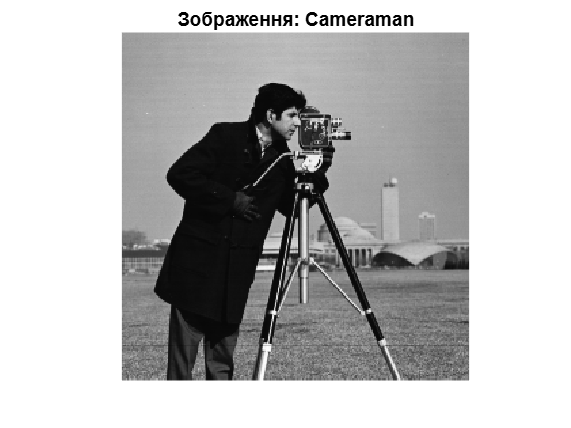

% Завантаження зображень з бібліотеки MATLAB
f1 = imread('cameraman.tif');
f2 = imread('moon.tif');
figure;
imshow(f1); title('Зображення: Cameraman');

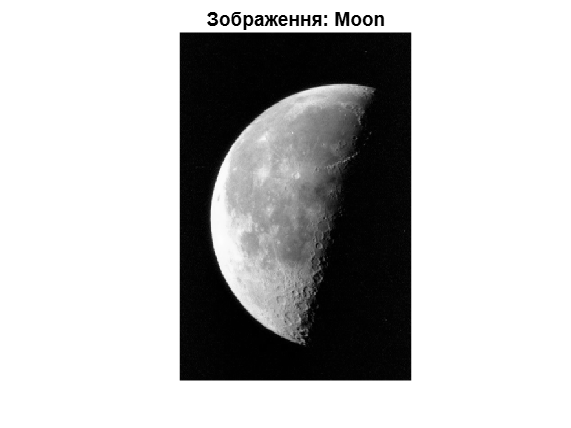

figure;
imshow(f2); title('Зображення: Moon');

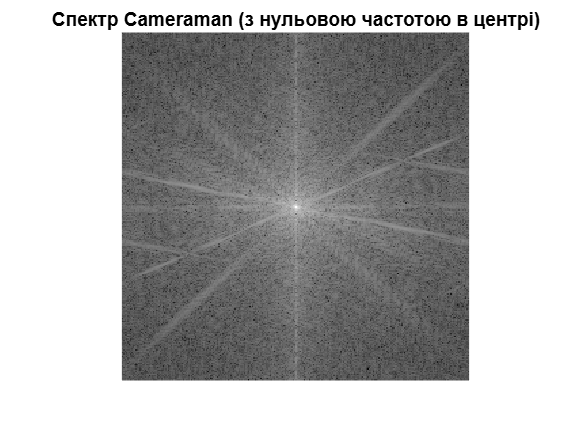


% Для cameraman.tif
F1 = fft2(f1);
S1 = abs(F1);
S1_log = log(1 + fftshift(S1)); % Логарифмічний масштаб + зсув нульової частоти

figure;
imshow(S1_log, []); 
title('Спектр Cameraman (з нульовою частотою в центрі)');

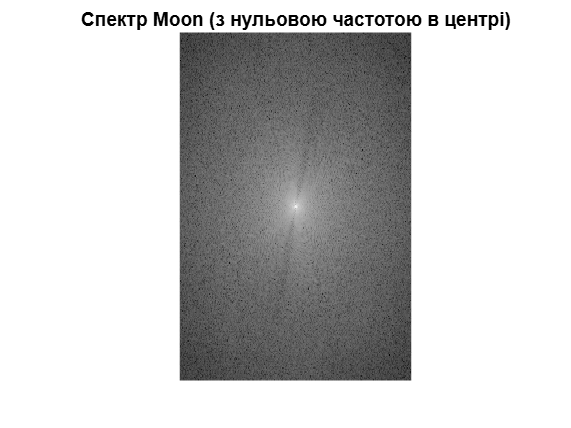


% Аналогічно для moon.tif
F2 = fft2(f2);
S2 = abs(F2);
S2_log = log(1 + fftshift(S2));

figure;
imshow(S2_log, []);
title('Спектр Moon (з нульовою частотою в центрі)');

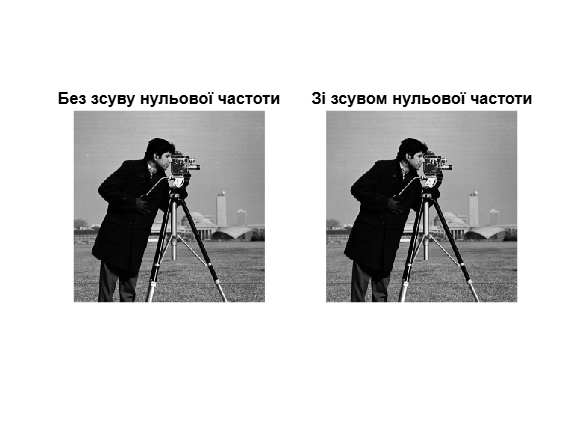


% Відновлення зображення без зсуву нульової частоти
If1 = ifft2(F1);
If1_abs = abs(If1);

% Відновлення зображення зі зсувом нульової частоти
F1_shifted = fftshift(F1);
If1_shifted = ifft2(ifftshift(F1_shifted));
If1_shifted_abs = abs(If1_shifted);

figure;
subplot(1,2,1); imshow(If1_abs, []); title('Без зсуву нульової частоти');
subplot(1,2,2); imshow(If1_shifted_abs, []); title('Зі зсувом нульової частоти');

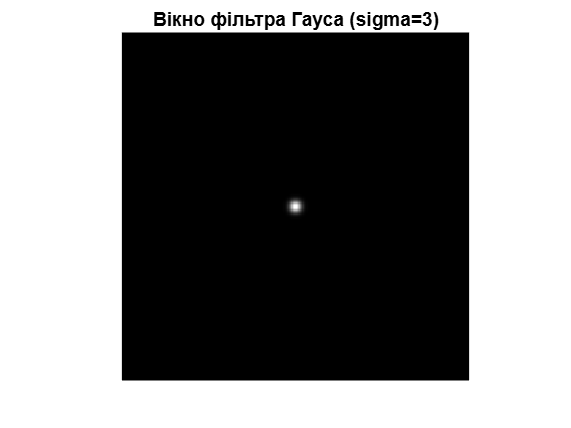


% Параметри фільтра
sigma = 3;
[M, N] = size(f1); % Розмір зображення cameraman (256x256)
h = fspecial('gaussian', [M N], sigma);

% Відображення вікна фільтра
figure;
imshow(h, []); 
title('Вікно фільтра Гауса (sigma=3)');

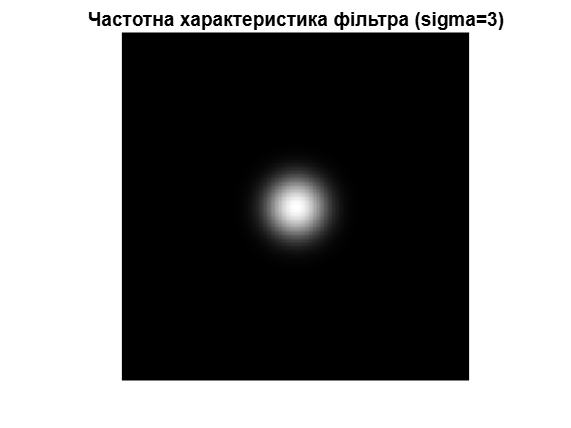


% Частотна характеристика фільтра
H = fft2(h);
H_shifted = fftshift(abs(H));
H_log = log(1 + H_shifted);

figure;
imshow(H_log, []); 
title('Частотна характеристика фільтра (sigma=3)');

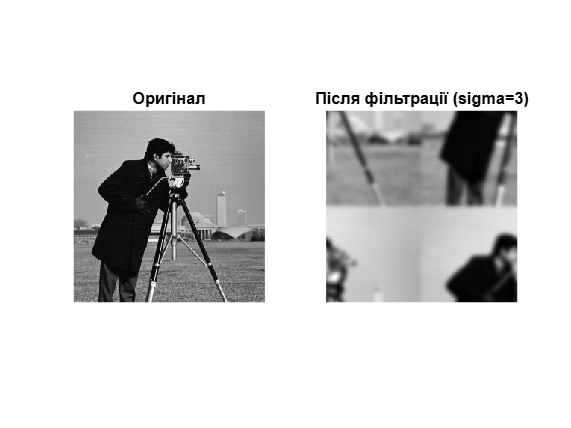


% Фільтрація зображення cameraman
F_filtered = F1 .* H; % Множення спектрів
f_filtered = ifft2(F_filtered);
f_filtered_abs = abs(f_filtered);

% Візуалізація
figure;
subplot(1,2,1); imshow(f1); title('Оригінал');
subplot(1,2,2); imshow(f_filtered_abs, []); title('Після фільтрації (sigma=3)');

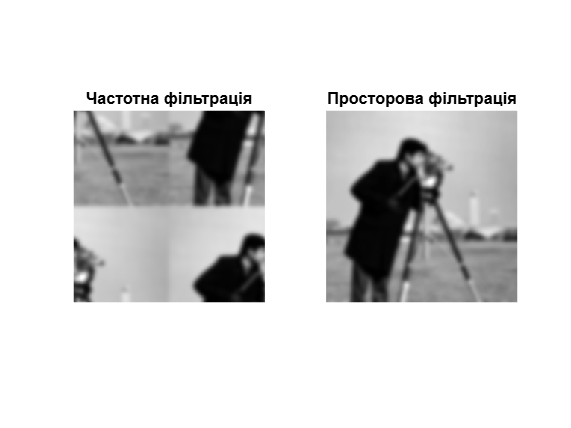


% Згортка з фільтром у просторовій області
h_spatial = fspecial('gaussian', 15, sigma); % Менший розмір вікна
f_spatial_filtered = imfilter(f1, h_spatial, 'replicate');

% Порівняння результатів
figure;
subplot(1,2,1); imshow(f_filtered_abs, []); title('Частотна фільтрація');
subplot(1,2,2); imshow(f_spatial_filtered, []); title('Просторова фільтрація');

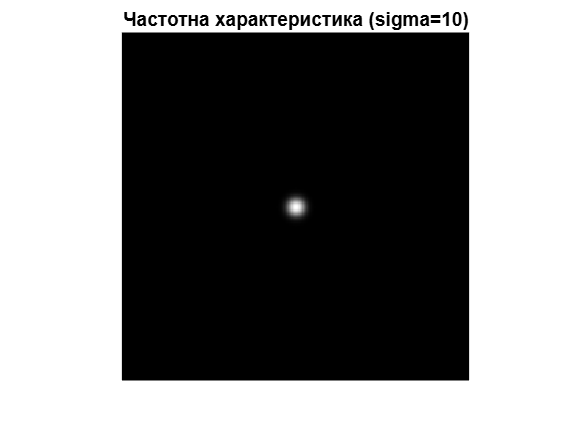


% Для sigma=10
sigma_new = 10;
h_new = fspecial('gaussian', [M N], sigma_new);
H_new = fft2(h_new);
H_new_shifted = fftshift(abs(H_new));
H_new_log = log(1 + H_new_shifted);

figure;
imshow(H_new_log, []); 
title('Частотна характеристика (sigma=10)');